## ***Task 1 – Energy and Energy Spectral Density***

 The following steps can be used to find the energy spectral density of a signal ‘x’ using  MATLAB:

1. Define N = length(x) 

2. Use fft(x)/fs to compute normalize fft of the signal. 

3. The above function gives the Fourier transform of the signal, which is not centered at  the zero frequency. In order to move the zero frequency component to the Enter center,  use fftshift( ). 

4. The Fourier transform is in complex form. Its magnitude spectrum can be obtained by  using the abs(_) function. 

5. The energy spectral density is simply the squared amplitude spectrum. 

The total energy of the signal can be obtained by taking the sum of the energy spectral density  and multiplying the result with fs/N.

## ***Exercise 1 ***

• Using sampling frequency to be 200, and time increment as 1/fs, generate a sinusoidal  signal with amplitude 5 and frequency 2 Hz, between -1 and 1 sec. 

• Add uniform noise using randn function. The resulting signal will be used as input  signal. Plot it against time. 

• Write a MATLAB code to compute and plot the energy spectral density of the signal.  You can define the frequency vector from (–N/2:N/2-1)*fs/N for the frequency  domain plot. 

What are the frequencies at which most of the energy of the signal is concentrated? 

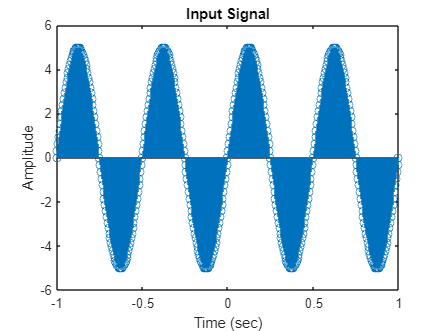

% Define sampling frequency and time increment
fs = 200;
dt = 1/fs;

% Define time vector
t = -fs/2:dt:fs/2-dt;

%subplot(5,1,1)
% Generate sinusoidal signal and ploting
x = 5*sin(2*pi*2*t);
stem(t, x);
xlim([-1 1]);
ylim([-6 6]);
xlabel('Time (sec)');
ylabel('Amplitude');
title('Input Signal');

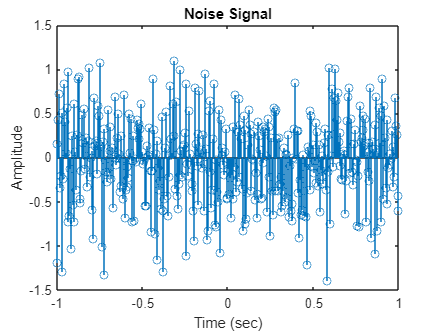


%subplot(5,1,2)
% Add uniform noise
noise = 0.5*randn(size(t));
stem(t, noise);
xlim([-1 1]);
xlabel('Time (sec)');
ylabel('Amplitude');
title('Noise Signal');

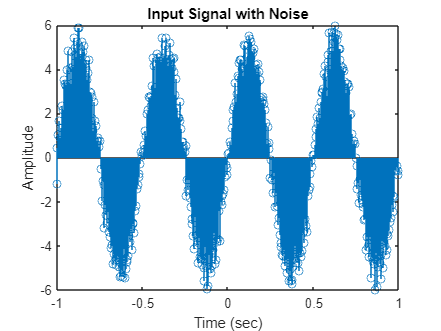


%subplot(5,1,3)
x_noise = x + noise;
% Plot signal against time
stem(t, x_noise);
xlim([-1 1]);
xlabel('Time (sec)');
ylabel('Amplitude');
title('Input Signal with Noise');



%subplot(5,1,4)
% Compute FFT and shift it
X = fftshift(fft(x_noise));
stem(t, X);

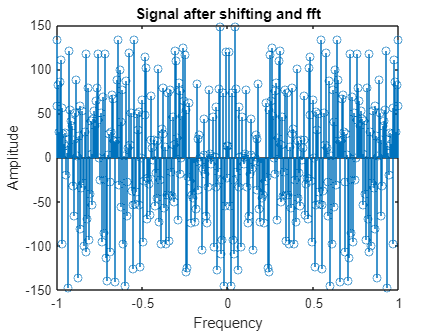

xlim([-1 1]);
xlabel('Frequency');
ylabel('Amplitude');
title('Signal after shifting and fft');

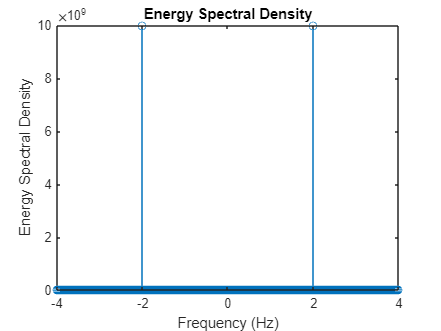



% Compute magnitude spectrum
X = abs(X);

% Compute energy spectral density
X = X.^2;

% Compute total energy
total_energy = sum(X)*dt*fs/length(x);

% Compute frequency vector
f = (-length(x)/2:1:length(x)/2-1)*fs/length(x);

% Plot energy spectral density against frequency
%subplot(5,1,5)
stem(f, X);
xlim([-4 4]);
xlabel('Frequency (Hz)');
ylabel('Energy Spectral Density');
title('Energy Spectral Density');


% Find frequencies at which most of the energy is concentrated
[max_energy, max_index] = max(X);
freqs_of_interest = f(max_index-5:max_index+5);

disp(['Frequencies at which most of the energy is concentrated: ', num2str(freqs_of_interest)]);

Frequencies at which most of the energy is concentrated: -2.025       -2.02      -2.015       -2.01      -2.005          -2      -1.995       -1.99      -1.985       -1.98      -1.975


## ***Exercise 2 ***

• Find the total energy of the signal by taking the sum of the square of its value at each  time instant and multiplying the final result with the time increment. 

• Find the total energy of the signal again by taking the sum of the energy spectral  density and multiplying the final result with fs/N. Compare the two results.

% Define sampling frequency and time increment
fs = 200;
dt = 1/fs;

% Define time vector
t = -fs/2:dt:fs/2-dt;

% Generate sinusoidal signal
x = 5*sin(2*pi*2*t);

% Add uniform noise
x = x + 0.5*randn(size(t));

% Compute energy of the signal at each time instant
energy_at_time = sum(x.^2)*dt;

% Compute total energy of the signal
total_energy = sum(energy_at_time)*dt;

% Compute FFT and shift it
X = fftshift(fft(x));

% Compute magnitude spectrum
X = abs(X);

% Compute energy spectral density
X = X.^2;

% Compute total energy of the signal using energy spectral density
total_energy_from_spectrum = sum(X)*fs/length(x);

% Compare the two results
disp(['Total energy of the signal computed using energy spectral density: ', num2str(total_energy_from_spectrum)]);

Total energy of the signal computed using energy spectral density: 101824121.2939


disp(['Total energy of the signal computed using energy at each time instant: ', num2str(total_energy)]);

Total energy of the signal computed using energy at each time instant: 12.728


## ***Task 2 – Power Spectral Density***

 The following steps can be used to find the energy spectral density of a signal ‘x’ using  MATLAB: 

1. Define N = length(x)

2. Find the average power of the signal. 

3. Find the Powerspectral density of signal by using pspectrum command. 

## ***Exercise 3***

 The signal y(t) is defined as below. This signal is sampled at 1000 samples per second.

  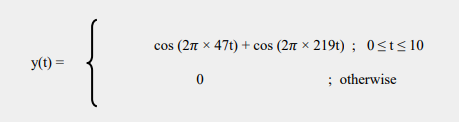

1. Plot the time domain signal y(t).  

2. Find the power spectral density of this signal.  

Change the frequencies of cosines as 100 Hz and 250 Hz and explain the difference. 


Fs = 1000; % Sampling frequency
t = 0:1/Fs:10;
y = cos(2*pi*47*t) + cos(2*pi*219*t);
N = length(y);
P = (norm(y)^2) / N

P = 1.0003

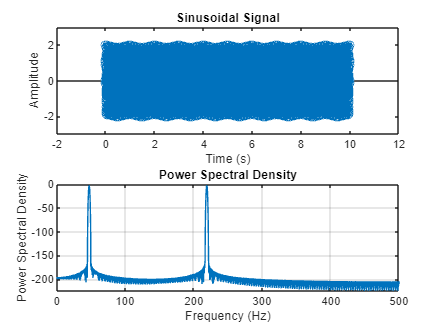


figure;
subplot(2,1,1);
stem(t, y);
axis([-2 12 -3 3]);
title('Sinusoidal Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2,1,2);
pspectrum(y, Fs);
title('Power Spectral Density');
xlabel('Frequency (Hz)');
ylabel('Power Spectral Density');